disp("By Abderrahim BELISSAOUI")

By Abderrahim BELISSAOUI


disp("A simple senario of SISO RADAR with Industrial and AWGN NOISES")

A simple senario of SISO RADAR with Industrial and AWGN NOISES


close all
clear all
clc

ParameterInit;
[cst1 cst2 s_s fb_max, fs, dt, fmin, fmax]=getparams(BW,fc,Rmax);
T=dt ;  % chirp duration

%% Waveform deisgn & Transmitted signal

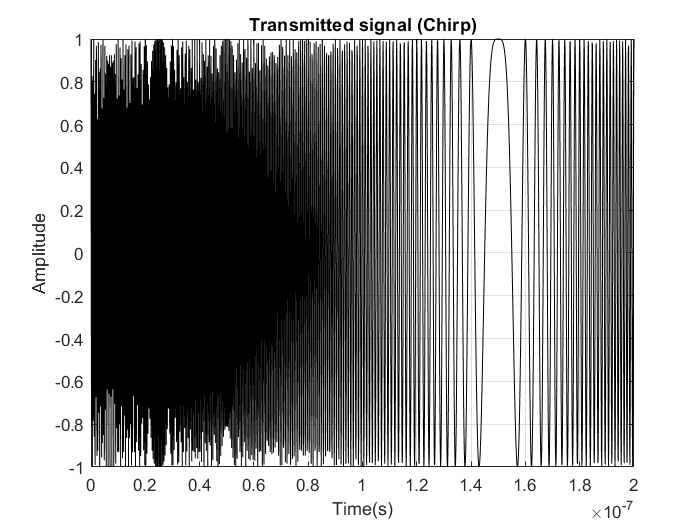


t=(0:1/fs:T); %base time

% t2= (dt:1/(10*fs):dt+dt/10); %inter-chirp
N=length(t) ;
% Inter=zeros(N,1)
% Inter=Inter' ;
% t=[t1,t2] ;
N_chirp=16 ; % number of transmitted chirps

f=(cst1+cst2*t) ;
% plot(t,f) ;grid on;
A=1;
TChirp = ShapePulse_chirp(t,cst1,cst2,A);  
% subplot(2,2,1)
figure(1)
plot(t,TChirp,'k'); grid on;
title('Transmitted signal (Chirp)');
xlabel('Time(s)');
ylabel('Amplitude');

% pspectrum(TChirp,fs,'spectrogram','TimeResolution',1000/fs, ...
%     'OverlapPercent',99,'Leakage',0.85)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
t2=repmat(t,1,2);
t_guard=zeros(1,300);
Tx_T=[TChirp t_guard] ;
Tx=repmat(Tx_T,1,N_chirp);
% figure(2);plot(Tx);grid on

t2=repmat(t,1,2);
t_guard=zeros(1,1000)+fmin;
f1=[f t_guard]  ;
f2=repmat(f1,1,N_chirp);
% figure(2);plot(f2); grid on;

## Received Signal

M=2; % Number of targets

% N_I=3; %% Number of interferers 

mindist=0.5;
maxdist=30;

minV=0.5;
maxV=60;

Vi=((maxV-minV)*rand(1,M)+minV)/3.6; %% en m/s !!!
Ri=(maxdist-mindist)*rand(1,M)+mindist; 

Bi=rand(1,M); %% canal de propagation!!!

tdi=Ri/(2*c);
fdi=fc*Vi/c; %% à vérifier pour systeme RADAR en tenant consideration l'angle!!!

rs=zeros(M,length(t));
% Bi=rand(1,M);

for i=1:M
    
sprintf("Target: %d Vit %d   Dist  %d    tdi: %.12f   fdi: %f\n",i,Vi(i),Ri(i),tdi(i),fdi(i))
rs(i,:)=ShapePulse_chirp(t-tdi(i),cst1+fdi(i),cst2,Bi(i));
% %  figure(i+1)
% %  plot(t,rs(i,:));
%  title(sprintf('Target %d',i));
%  xlabel('Time(s)');
%  ylabel('Amplitude'); 
end

ans =     "Target: 1 Vit 5.639897e+00   Dist  2.997253e+01    tdi: 0.000000049954   fdi: 1485.172856
     "


ans =     "Target: 2 Vit 1.145620e+01   Dist  1.646788e+01    tdi: 0.000000027446   fdi: 3016.798824
     "


Rs_Whi_I=sum(rs,1);
% Mixed signal contains M targets echo and noise
SNR_db=[1 10 20 30] ;
Calibre=[10 30 50] ;
disp(["Number of cases=", num2str(length(SNR_db)*length(Calibre))]);

    "Number of cases="    "12"



    "Calibre value="    "10"



    "SNR value="    "1"



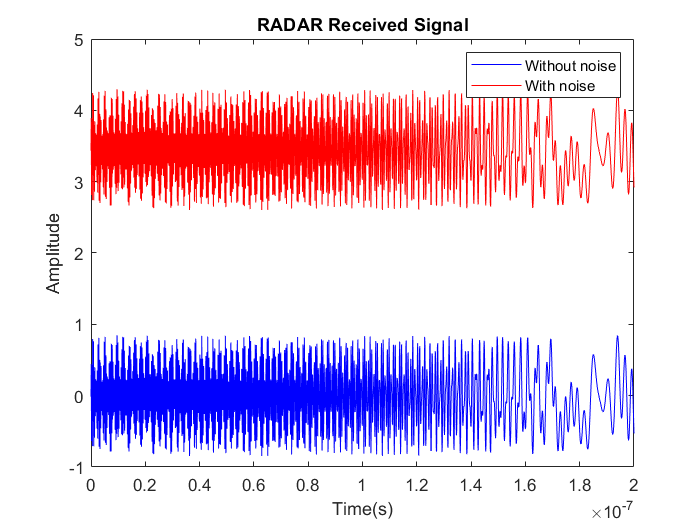

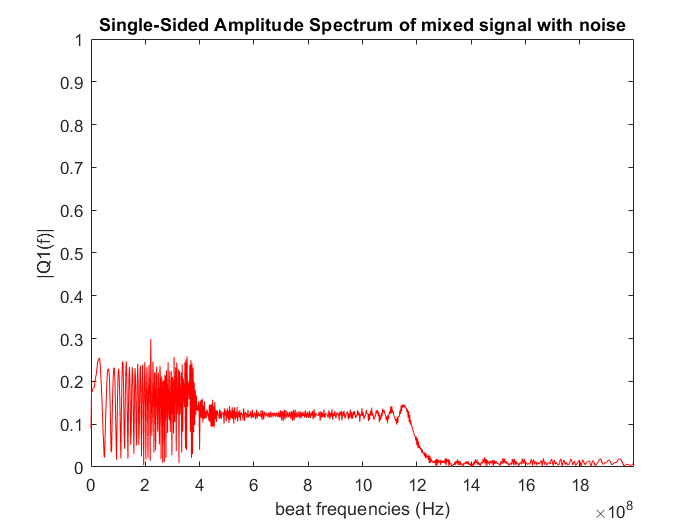

    "Calibre value="    "10"



    "SNR value="    "10"



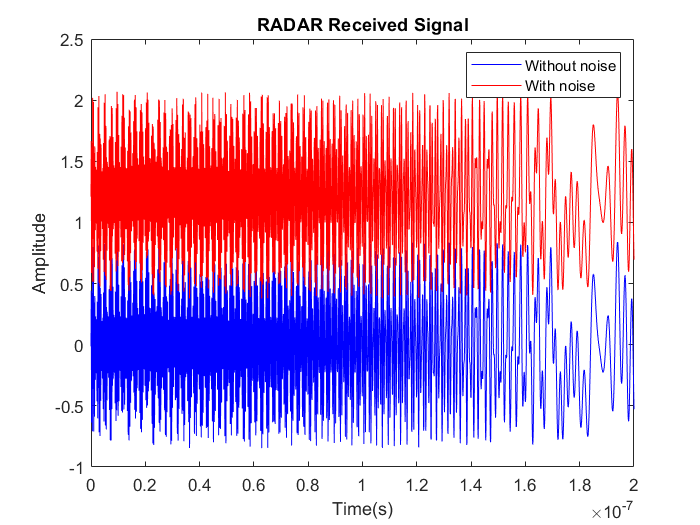

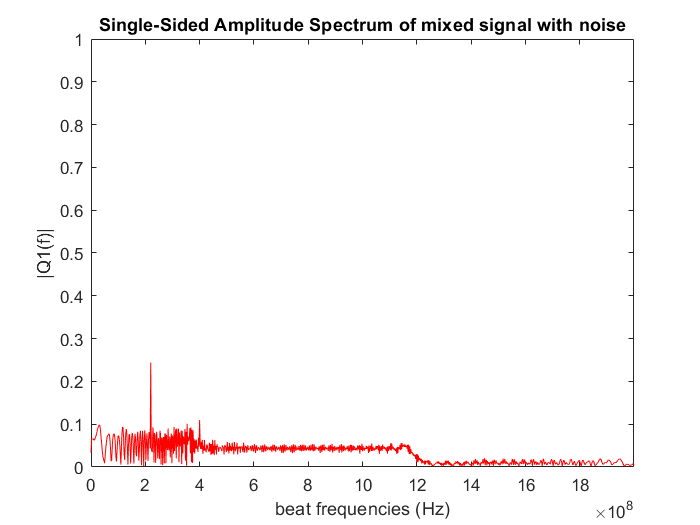

    "Calibre value="    "10"



    "SNR value="    "20"



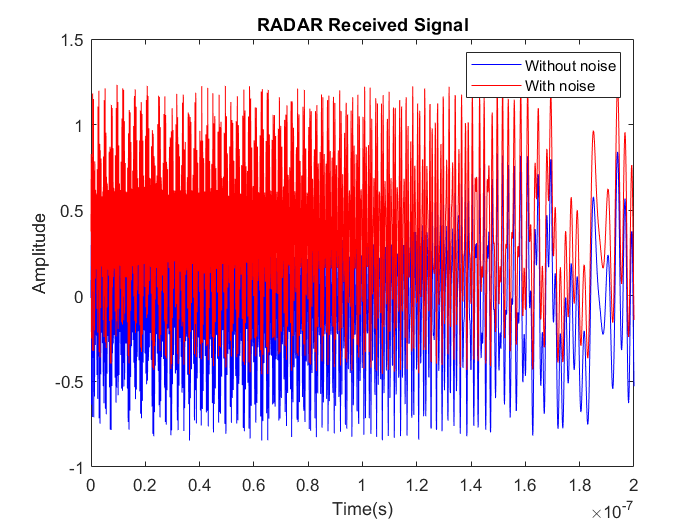

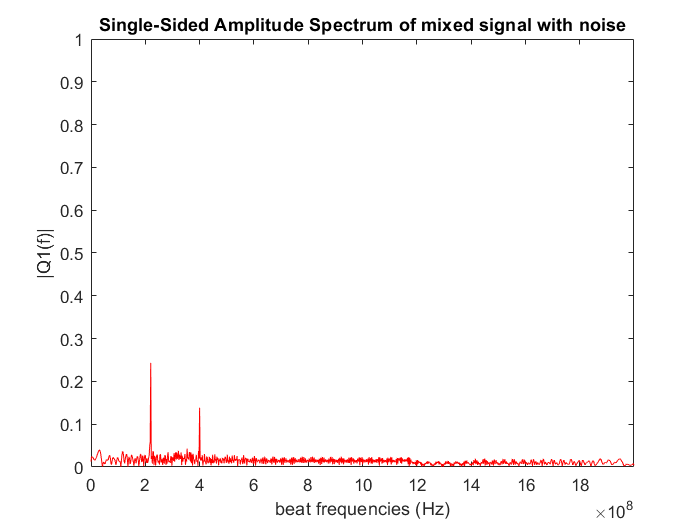

    "Calibre value="    "10"



    "SNR value="    "30"



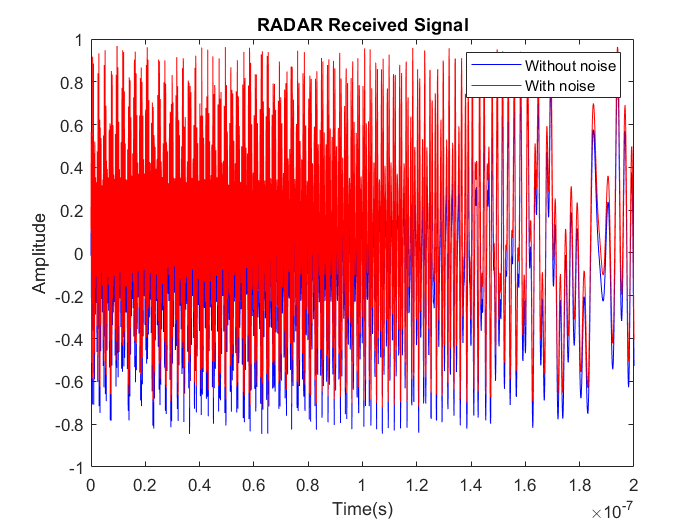

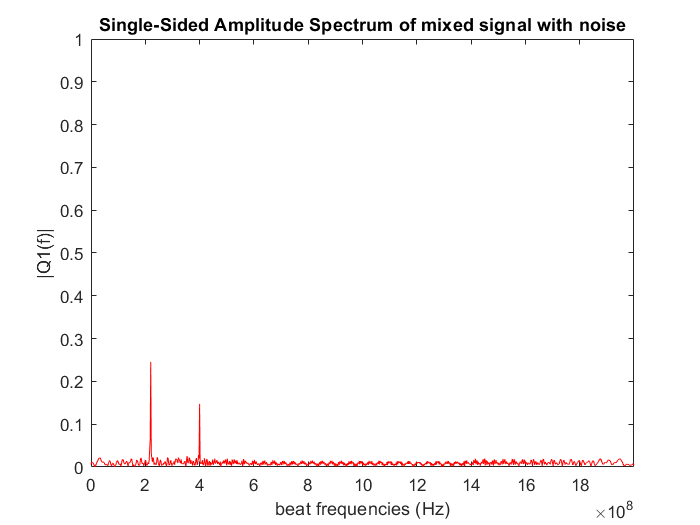

    "Calibre value="    "30"



    "SNR value="    "1"



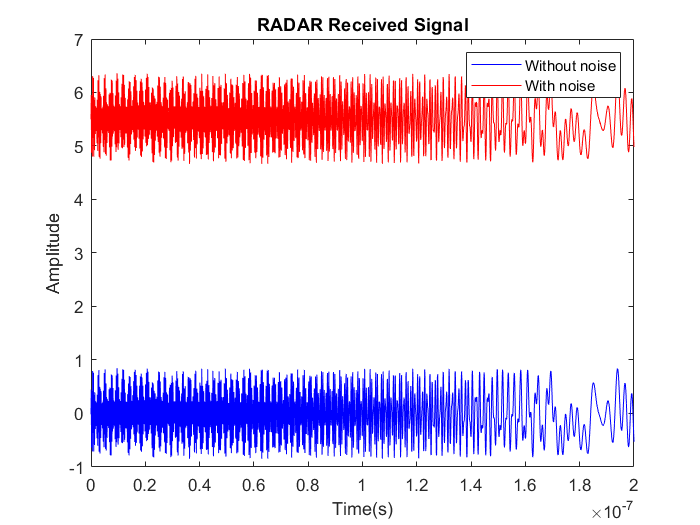

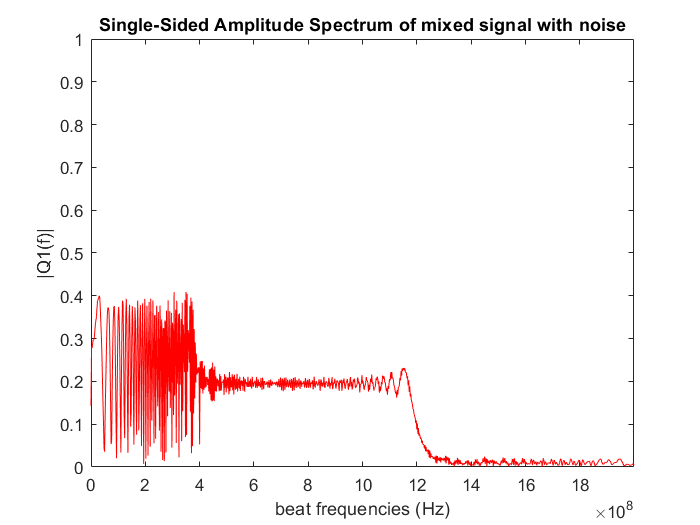

    "Calibre value="    "30"



    "SNR value="    "10"



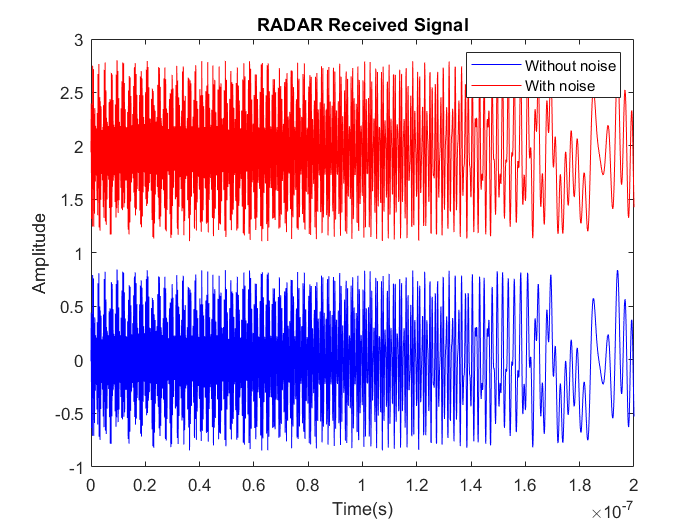

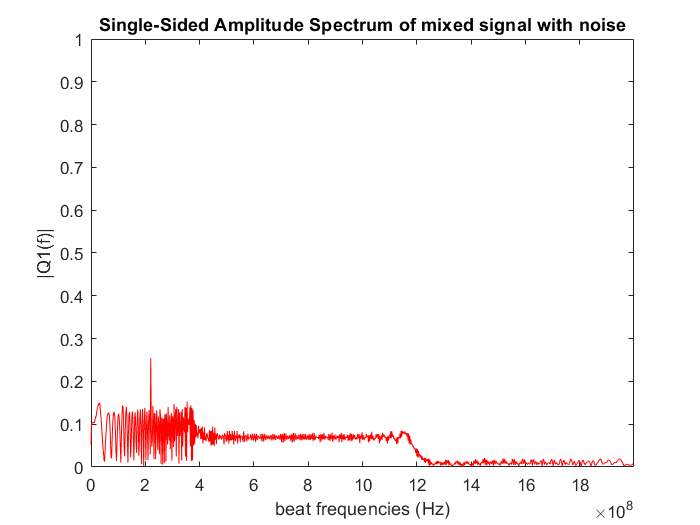

    "Calibre value="    "30"



    "SNR value="    "20"



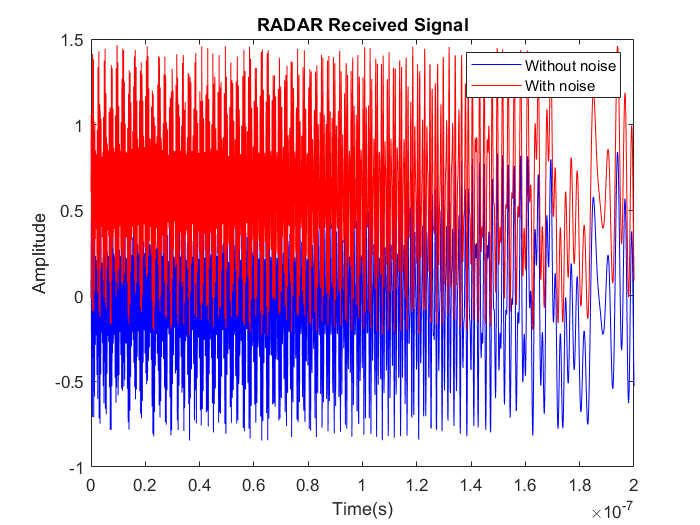

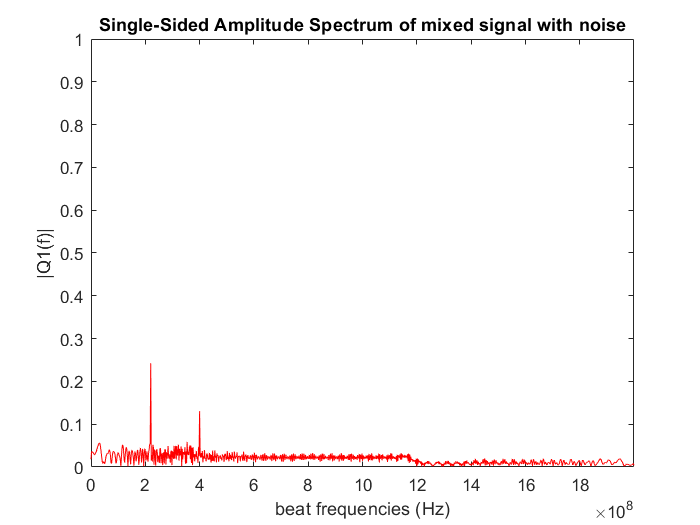

    "Calibre value="    "30"



    "SNR value="    "30"



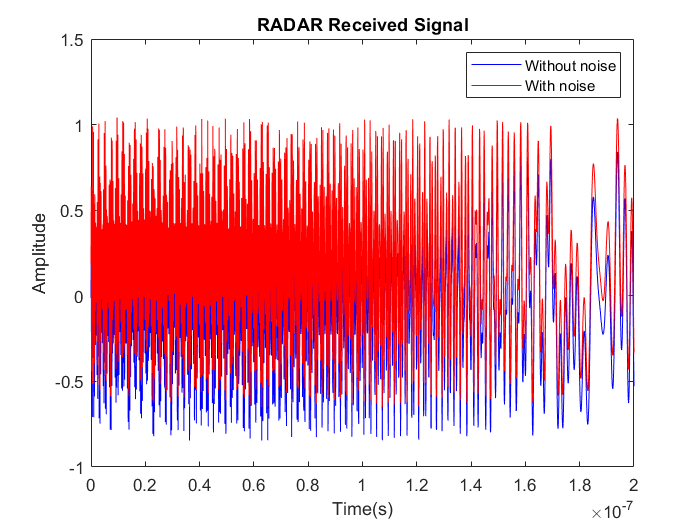

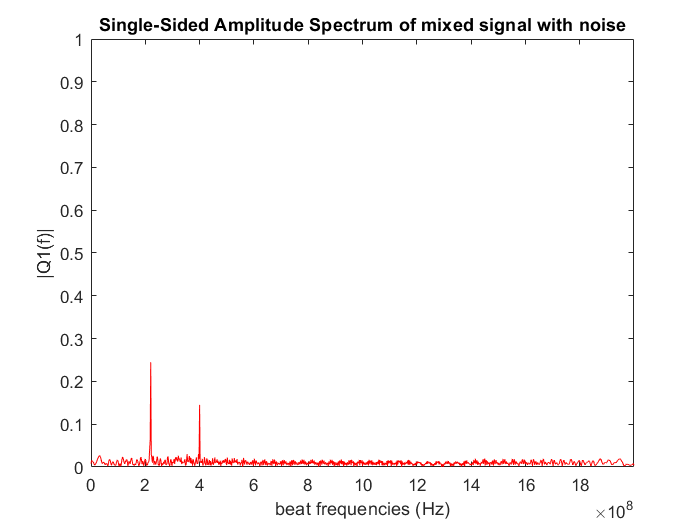

    "Calibre value="    "50"



    "SNR value="    "1"



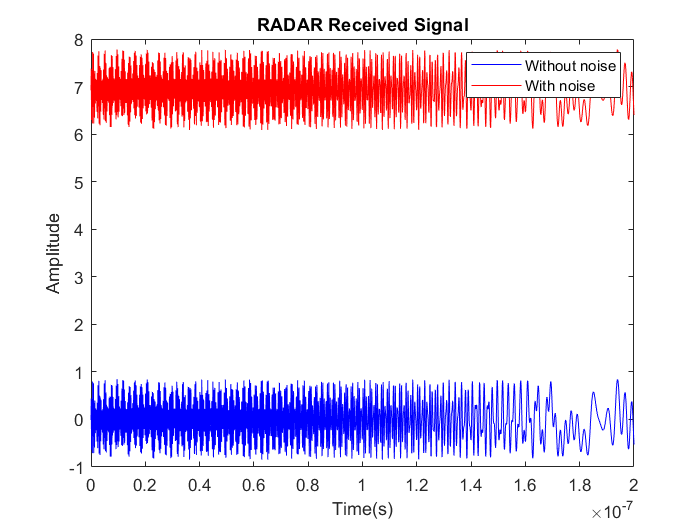

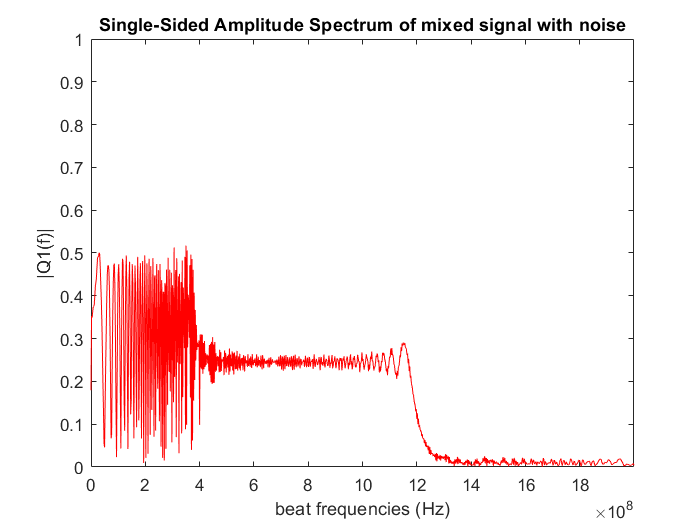

    "Calibre value="    "50"



    "SNR value="    "10"



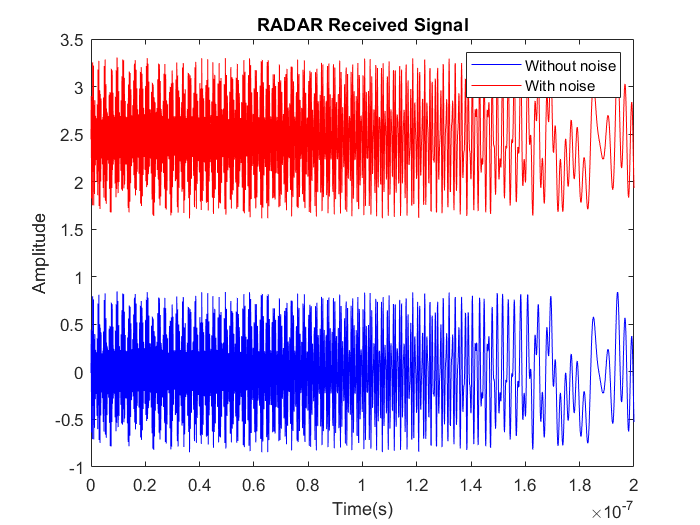

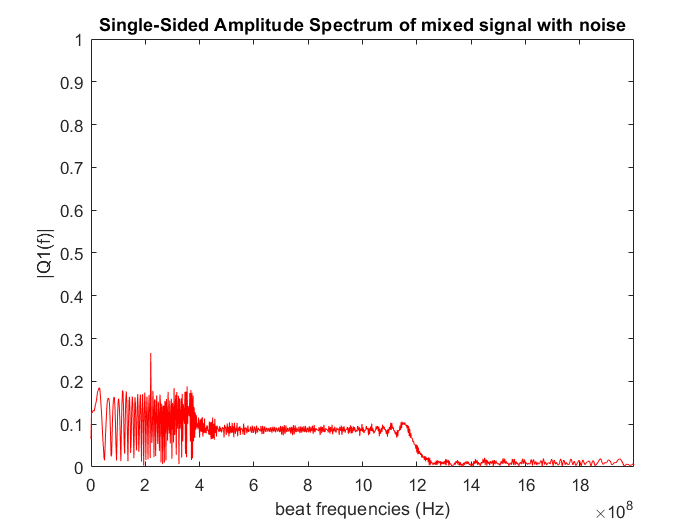

    "Calibre value="    "50"



    "SNR value="    "20"



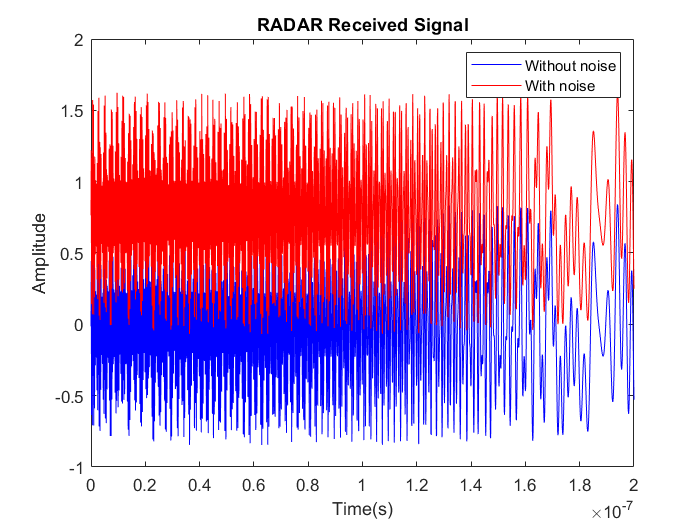

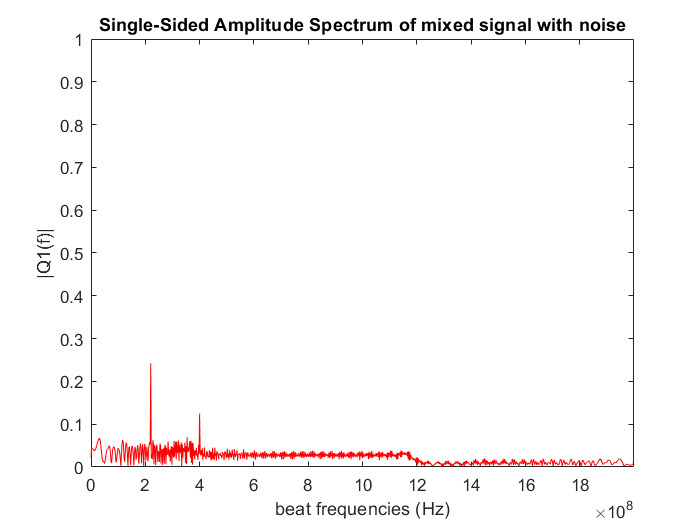

    "Calibre value="    "50"



    "SNR value="    "30"



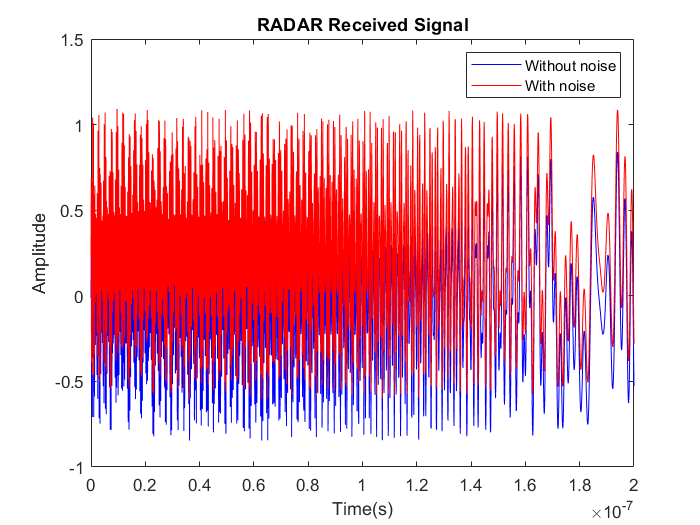

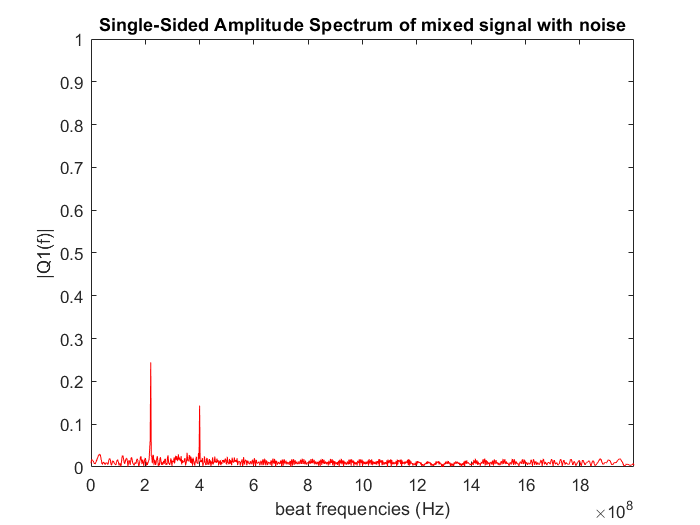

%================ noise effect for different SNR and Calibre
for j=1:length(Calibre)
for i=1:length(SNR_db)
    
    disp(["Calibre value=", num2str(Calibre(j))]) %% calibre
    disp(["SNR value=", num2str(SNR_db(i))]); %  SNR: Signal to noise ratio
    [sigma1,sigma2]= AddNoise(SNR_db(i),Calibre(j),Rs_Whi_I);  %% i= snr  and j calibre
    Signal_tot=Rs_Whi_I+sigma1+sigma2; %total signal
    figure
    plot(t,Rs_Whi_I,'b')
    hold on
    plot(t,Signal_tot,'r')
    title ('RADAR Received Signal')
    legend({'Without noise ','With noise'},'Location','northeast')
    xlabel('Time(s)'); ylabel('Amplitude');
% =====================mixed signal==============
    mixed11=(TChirp.*Signal_tot); 
    L=length(mixed11) ;
    Y= fft(mixed11);

% =====================DETECTION -Range FFT=======================
   Q2 = abs(Y/L);
   Q1 = Q2(1:L/2+1);
   Q1(2:end-1) = 2*Q1(2:end-1);
   f = fb_max*(0:(L/2))/L;
   % r= c*f/(2*s_s);
   figure
   plot(f,Q1,'r') 
   axis([0 max(f) 0 1]) ;
   title('Single-Sided Amplitude Spectrum of mixed signal with noise')
   xlabel('beat frequencies (Hz)')
   ylabel('|Q1(f)|')
 end
 end

% R= addGaussianNoise(Rs_Whi_I,0);

% figure
% 
% % plot(t,Rs_Whi_I);
% % title('Received Signal: All Targets ');
% % xlabel('Time(s)');
% % ylabel('Amplitude');
% 
% % R=awgn(Rs_Whi_I,10,'measured') ; %% add AWGN noise to the received signal
% % %%
% hold on
% plot(t,Rs_Whi_I,'r');
% plot(t,R,'b');
% legend('Received signal without noise','Received signal with noise')
% title('Received Signal with & without noise');
% xlabel('Time(s)'); ylabel('Amplitude');


% Mixed signal contains M targets echo and noise

% SNR=20;
% Rs=awgn(Rs_Whi_I,SNR,'measured') ;
% mixed1=(TChirp.*Rs); 
% L=length(mixed1) ;
% Y = fft(mixed1);
% % X = fft2(abs(Y));
% % imagesc(abs(fftshift(X))) ;
% 
% 
% 
% Q2 = abs(Y/L);
% Q1 = Q2(1:L/2+1);
% Q1(2:end-1) = 2*Q1(2:end-1);
% f = fs*(0:(L/2))/L;
% figure
% plot(f,Q1) 
% title('Single-Sided Amplitude Spectrum of mixed signal')
% xlabel('f (Hz)')
% ylabel('|Q1(f)|')

% %% Interference  
% N=randperm(M); %% Number of interferers N must be inferior of number of targets
% N_I=N(1); % take the first value of N 
% 
% mindist=0.5; %% Interferer min range
% maxdist=200; %% Interferer max range
% 
% minV=0;% doppler equal to zero
% maxV=0;
% 
% ri_I=zeros(N_I,length(t)); %% matrix of zeros with a number of N_I lines and a number of columns equal to length(t)
% 
% for j=1:N_I
% Vi_I=((maxV-minV)*rand(1,N_I)+minV)/3.6; %%  in m/s !!!
% Ri_I=(maxdist-mindist)*rand(1,N_I)+mindist; 
% 
% Bi_I=rand(4,N_I); %% propagation channel!!! 
% 
% % Get random Range from 1 to 3
% idx=randperm(3);% index
% fci_I=fc_I(idx(1));
% tdi_I=Ri_I/(2*c);
% fdi_I=fci_I*Vi_I/c; %% à vérifier pour systeme RADAR en tenant consideration l'angle!!!
% BWi_I=BW_I(idx(1));
% 
% disp(strcat('Interferer type ', interferer{idx(1)})) ;
% 
% [cst1i_I cst2i_I s_s  fs, dt]=getparams(BWi_I,fci_I,Rmax);
% 
%     ri_I(j,:)=ShapePulse_chirp(t-tdi_I(j),cst1i_I+fdi_I(j),cst2i_I,Bi_I(j));
% 
% end
% 
% R_I=sum(ri_I,1);
%  
% figure(3)
% plot(t,R_I);
% title('Received Interferer Component');
% xlabel('Time(s)');
% ylabel('Amplitude');
% Rs_Whi_I=Rs_Whi_I+R_I ;

    "SNR value="    "1"



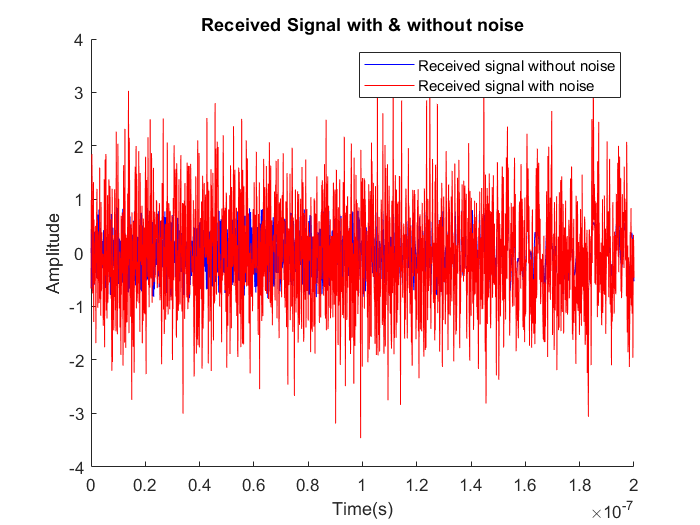

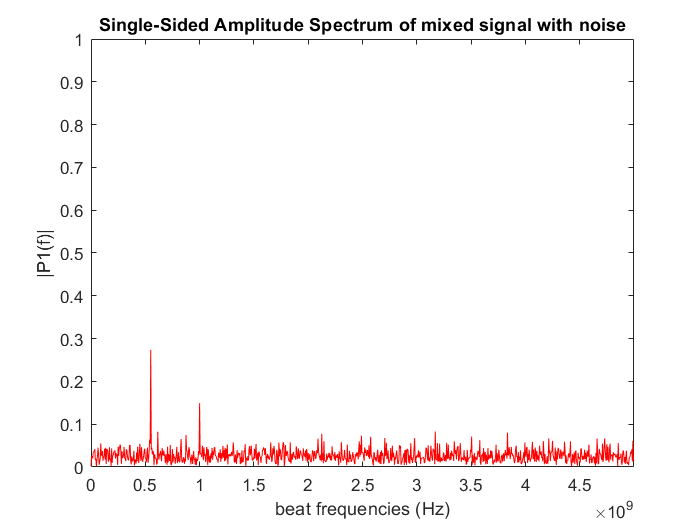

    "SNR value="    "10"



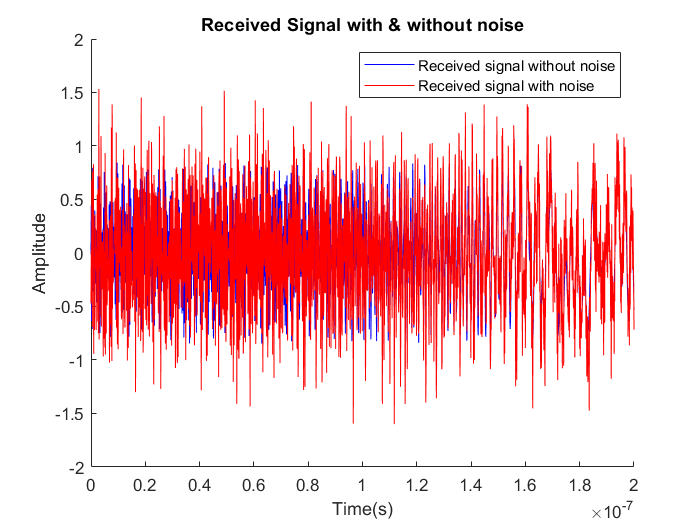

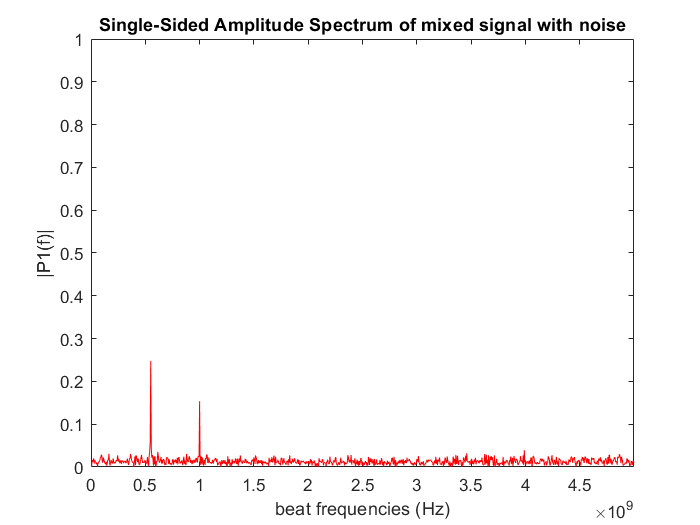

    "SNR value="    "20"



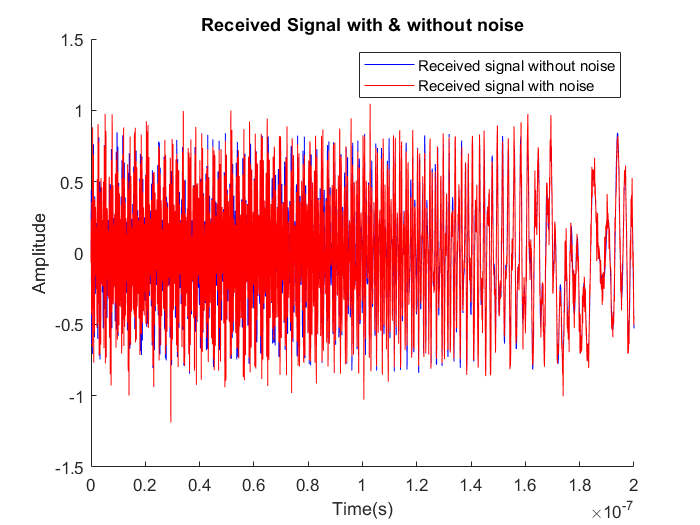

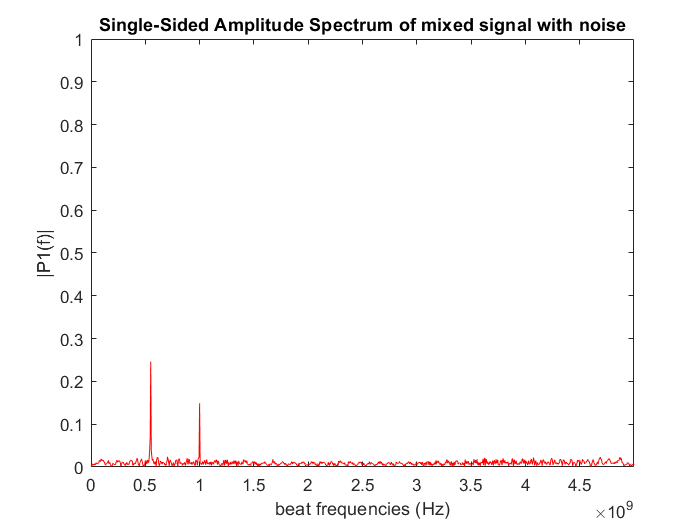

    "SNR value="    "30"



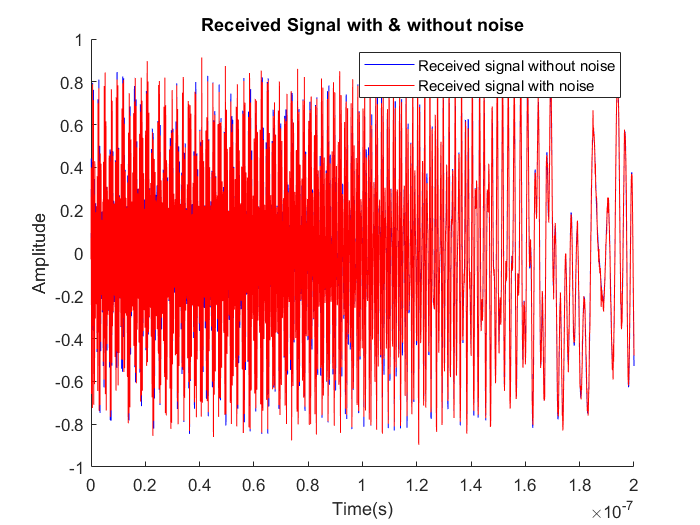

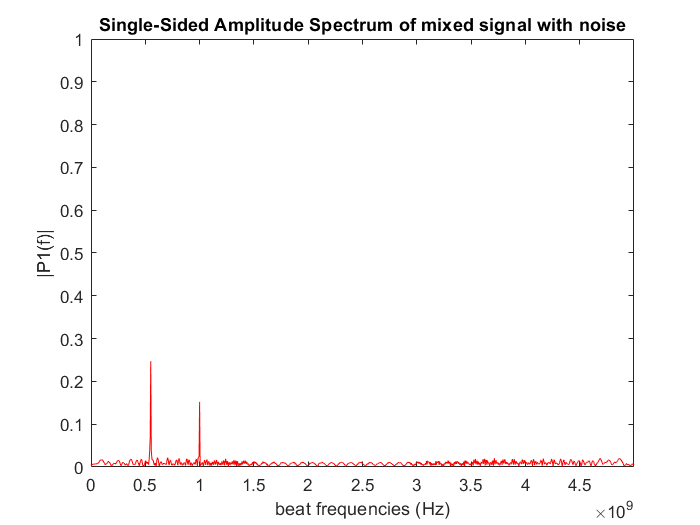

%% ================SNR based AWGN matlab function =====================
SNR_db=[1 10 20 30] ;
for i=1:length(SNR_db)
    disp(["SNR value=", num2str(SNR_db(i))]); %  SNR: Signal to noise ratio
    R=awgn(Rs_Whi_I,SNR_db(i)) ; %% add AWGN noise to the received signal
    % %%
    figure
    hold on
    plot(t,Rs_Whi_I,'b');
    plot(t,R,'r');
    legend('Received signal without noise','Received signal with noise')
    title('Received Signal with & without noise');
    xlabel('Time(s)'); ylabel('Amplitude');
    mixed=(TChirp.*R);
    L=length(mixed) ;
    Y = fft(mixed);
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = fs*(0:(L/2))/L;
    figure 
    plot(f,P1,'r') 
   axis([0 max(f) 0 1]) ;
   title('Single-Sided Amplitude Spectrum of mixed signal with noise')
   xlabel('beat frequencies (Hz)')
    ylabel('|P1(f)|')
end

% rngdopresp = phased.RangeDopplerResponse('PropagationSpeed',3e8,...
%     'DopplerOutput','Speed','OperatingFrequency',79e9,'SampleRate',fs,...
%     'RangeMethod','FFT','SweepSlope',s_s,...
%     'RangeFFTLengthSource','Property','RangeFFTLength',2048,...
%     'DopplerFFTLengthSource','Property','DopplerFFTLength',256);
% 
% clf;
% plotResponse(rngdopresp,mixed);                     % Plot range Doppler map
% axis([-60 60 0 30])
% clim = caxis;

% disp ( "case 2 : SNR=10dB")
% R=awgn(Rs_Whi_I,10,'measured') ; %% add AWGN noise to the received signal
% %%
% % hold on
% % plot(t,Rs_Whi_I,'r');
% % plot(t,R,'b');
% % legend('Received signal without noise','Received signal with noise')
% % title('Received Signal with & without noise');
% % xlabel('Time(s)'); ylabel('Amplitude');
% mixed=(TChirp.*R);
% L=length(mixed) ;
% Y = fft(mixed);
% P2 = abs(Y/L);
% P1 = P2(1:L/2+1);
% P1(2:end-1) = 2*P1(2:end-1);
% f = fs*(0:(L/2))/L;
% figure
% plot(f,P1) 
% title('Single-Sided Amplitude Spectrum of mixed signal')
% xlabel('f (Hz)')
% ylabel('|P1(f)|')

% disp ( "case 3 : SNR=20dB")
% R=awgn(Rs_Whi_I,20,'measured') ; %% add AWGN noise to the received signal
% % %%
% % hold on
% % plot(t,Rs_Whi_I,'r');
% % plot(t,R,'b');
% % legend('Received signal without noise','Received signal with noise')
% % title('Received Signal with & without noise');
% % xlabel('Time(s)'); ylabel('Amplitude');
% mixed=(TChirp.*R);
% L=length(mixed) ;
% Y = fft(mixed);
% P2 = abs(Y/L);
% P1 = P2(1:L/2+1);
% P1(2:end-1) = 2*P1(2:end-1);
% f = fs*(0:(L/2))/L;
% figure
% plot(f,P1) 
% title('Single-Sided Amplitude Spectrum of mixed signal')
% xlabel('f (Hz)')
% ylabel('|P1(f)|')

% disp ( "case 4 : SNR=20dB")
% R=awgn(Rs_Whi_I,10,'measured') ; %% add AWGN noise to the received signal
% %%
% hold on
% plot(t,Rs_Whi_I,'r');
% plot(t,R,'b');
% legend('Received signal without noise','Received signal with noise')
% title('Received Signal with & without noise');
% xlabel('Time(s)'); ylabel('Amplitude');
% mixed=(TChirp.*R);
% L=length(mixed) ;
% Y = fft(mixed);
% P2 = abs(Y/L);
% P1 = P2(1:L/2+1);
% P1(2:end-1) = 2*P1(2:end-1);
% f = fs*(0:(L/2))/L;
% figure
% plot(f,P1) 
% title('Single-Sided Amplitude Spectrum of mixed signal')
% xlabel('f (Hz)')
% ylabel('|P1(f)|')

% Mixed Signal contains M targets echo and noise and N interferer

% mixed=(TChirp.*R);
% L=length(mixed) ;
% Y = fft(mixed);
% P2 = abs(Y/L);
% P1 = P2(1:L/2+1);
% P1(2:end-1) = 2*P1(2:end-1);
% f = fs*(0:(L/2))/L;
% figure
% plot(f,P1) 
% title('Single-Sided Amplitude Spectrum of mixed signal')
% xlabel('f (Hz)')
% ylabel('|P1(f)|')
% mixed=(TChirp.*R);
% L=length(mixed) ;
% Y = fft(mixed);
% P2 = abs(Y/L);
% P1 = P2(1:L/2+1);
% P1(2:end-1) = 2*P1(2:end-1);
% f = fs*(0:(L/2))/L;
% figure
% plot(f,P1) 
% title('Single-Sided Amplitude Spectrum of mixed signal')
% xlabel('f (Hz)')
% ylabel('|P1(f)|')



% lowpass(mixed,fb_max,2.5*fb_max) ;


% Range=(f*c*dt)/(2*BW) ;
% plot(Range,power)
% xlabel('Range')
% ylabel('Power')

% 
% L=160; %% side of sliding window
% [mlmax_F,mlmax_B,r,m_new] = WEN(mixed,L);
% %Forward-sliding window maxim
% figure('name','Forward sliding');
% plot(t,mlmax_F);
% xlabel('time(s)');
% ylabel('Amplitude');

% figure('name','Envelop');
% plot(t,r);
% xlabel('time(s)');
% ylabel('Amplitude');

% figure('name','normalized mixer output');
% plot(t,m_new);
% xlabel('time(s)');
% ylabel('Amplitude');
% % plot(abs(fft(m_new)))
% % lowpass(m_new,fb_max,2.5*fb_max) ;


% L=length(m_new) ;
% Y = fft(m_new);
% F2 = abs(Y/L);
% F1 = F2(1:L/2+1);
% F1(2:end-1) = 2*F1(2:end-1);
% f = fs*(0:(L/2))/L;
% figure
% plot(f,F1) 
% title('Single-Sided Amplitude Spectrum of mixed signal')
% xlabel('f (Hz)')
% ylabel('|F1(f)|')
